***句柄/窗口控制***

x=1:10;
y=x.^2;
h=plot(x,y);
h1=text(5,25,'说明');
h1.FontSize=24

h1 =   Text (说明) - 属性:

                 String: '说明'
               FontSize: 24
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [5 25 0]
                  Units: 'data'

  显示 所有属性


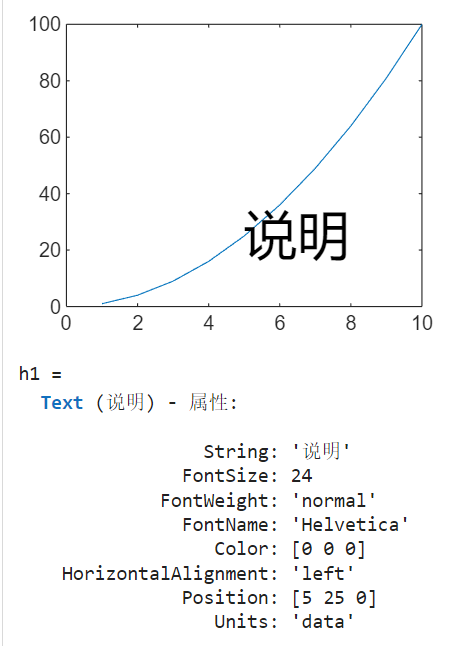

获取某个对象的说明:

get函数:

set函数:

x=linspace(0,2*pi,100);
y=sin(x);
h=plot(x,y);
get(h)

      AffectAutoLimits: on
    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0 0.447 0.741]
             ColorMode: 'auto'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: '-'
         LineStyleMode: 'auto'
             LineWidth: 0.5
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44

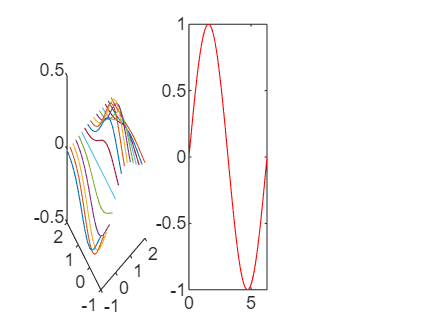

set(h,'Color','red')

图形窗口设置:

图形窗口的分割:

子图:同一个图形窗口的不同坐标系下的图形为子图

subplot函数:

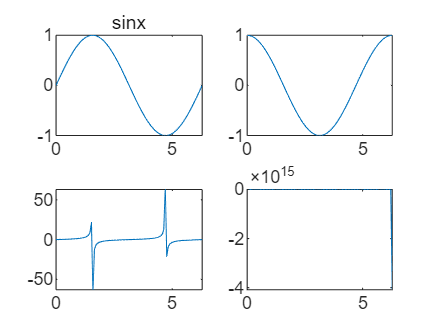

x=linspace(0,2*pi,100);
subplot(2,2,1)
plot(x,sin(x));
title('sinx')

subplot(2,2,2)
plot(x,cos(x));
subplot(2,2,3)
plot(x,tan(x));
subplot(2,2,4)
plot(x,cot(x));

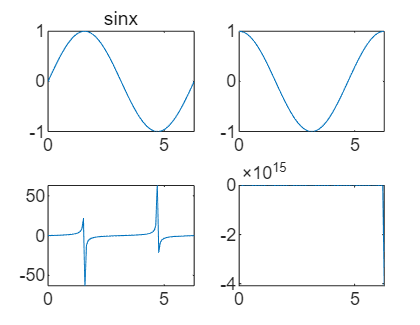

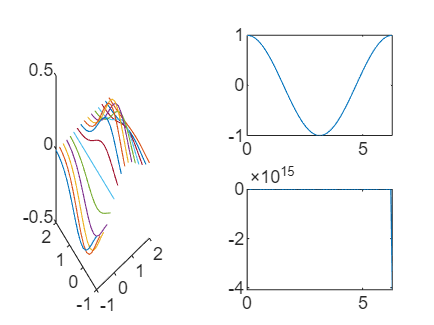

x=-1:0.2:2;
[X,Y]=meshgrid(x);
Z=X.*exp(-X.^2-Y.^2);
subplot(1,3,1)
plot3(X,Y,Z)

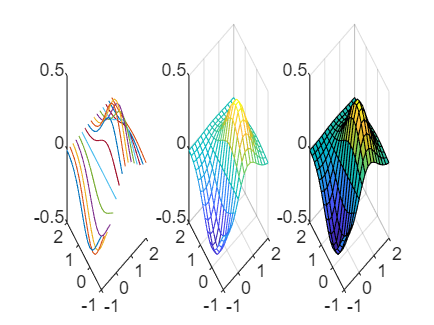

subplot(1,3,2)
mesh(X,Y,Z)
subplot(1,3,3)
surf(X,Y,Z)